## Condiciones iniciales de arfada

syms a1(t) a2(t) a3(t) a4(t) a5(t)  T A
syms v1(t) v2(t) v3(t) v4(t) v5(t)  
syms x1(t) x2(t) x3(t) x4(t) x5(t) 
assume(T>0)
assume(A>0)
g=9.81;
xMax=0.1

xMax = 0.1000

aMax=g/2

aMax = 4.9050

A=aMax;


## Aceleración

a1(t)=10*A/T*t;

a2(t)=A;

a3(t)=-10*A/T*t;
Ca3=A-a3(4*T/10);
a3(t)=a3(t)+Ca3;
a4(t)=-A;
a5(t)=10*A/T*t;
Ca5=a4(9*T/10)-a5(9*T/10);
a5(t)=a5(t)+Ca5;
fprintf('Función de aceleración:')

Función de aceleración:

a(t)=piecewise((0<=t<T/10),a1,(T/10<=t<4*T/10),a2,(4*T/10<=t<6*T/10),a3,(6*T/10<=t<9*T/10),a4,(9*T/10<=t<=T),a5)

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{981}{200} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{981}{40}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ -\frac{981}{200} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \sigma_{1}-\frac{981}{20} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,t}{20\,T} \end{array}$$

## Velocidad


v1(t)=int(a1);

v2(t)=int(a2);
Cv2=v1(T/10)-v2(T/10);
v2(t)=v2(t)+Cv2;

v3(t)=int(a3);
Cv3=v2(4*T/10)-v3(4*T/10);
v3(t)=v3(t)+Cv3;

v4(t)=int(a4);
Cv4=v3(6*T/10)-v4(6*T/10);
v4(t)=v4(t)+Cv4;

v5(t)=int(a5);
Cv5=v4(9*T/10)-v5(9*T/10);
v5(t)=v5(t)+Cv5;

fprintf('Función de velocidad:')

Función de velocidad:

v(t)=piecewise((0<=t<T/10),v1,(T/10<=t<4*T/10),v2,(4*T/10<=t<6*T/10),v3,(6*T/10<=t<9*T/10),v4,(9*T/10<=t<=T),v5)

$$v(t) = \left\{ \begin{array}{cl} \frac{981\,t^{2}}{40\,T} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{981\,t}{200}-\frac{981\,T}{4000} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ -\frac{16677\,T}{4000}-\frac{t\,\left(\frac{981\,t}{T}-981\right)}{40} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{18639\,T}{4000}-\frac{981\,t}{200} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{981\,T}{40}+\frac{t\,\left(\frac{981\,t}{2\,T}-981\right)}{20} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.$$

## Desplazamiento


z1(t)=int(v1);

z2(t)=int(v2);
Cz2=z1(T/10)-z2(T/10);
z2(t)=z2(t)+Cz2;

z3(t)=int(v3);
Cz3=z2(4*T/10)-z3(4*T/10);
z3(t)=z3(t)+Cz3;

z4(t)=int(v4);
Cz4=z3(6*T/10)-z4(6*T/10);
z4(t)=z4(t)+Cz4;

z5(t)=int(v5);
Cz5=z4(9*T/10)-z5(9*T/10);
z5(t)=z5(t)+Cz5;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

Fz_arfada(t)=piecewise((0<=t<T/10),z1,(T/10<=t<4*T/10),z2,(4*T/10<=t<6*T/10),z3,(6*T/10<=t<9*T/10),z4,(9*T/10<=t<=T),z5)

$$Fz\_arfada(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }10\,t<T\wedge 0\leq t\\ \frac{327\,T^{2}}{40000}-\frac{981\,t\,\left(T-10\,t\right)}{4000} & \text{ if }T\leq 10\,t\wedge 5\,t<2\,T\\ \frac{4251\,T^{2}}{8000}-\frac{16677\,T\,t}{4000}+\frac{981\,t^{2}}{80}-\sigma_{1} & \text{ if }5\,t<3\,T\wedge 2\,T\leq 5\,t\\ \frac{981\,t\,\left(19\,T-10\,t\right)}{4000}-\frac{49377\,T^{2}}{40000} & \text{ if }10\,t<9\,T\wedge 3\,T\leq 5\,t\\ \frac{327\,t\,\left(3\,T^{2}-3\,T\,t+t^{2}\right)}{40\,T}-\frac{3597\,T^{2}}{500} & \text{ if }t\leq T\wedge 9\,T\leq 10\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{327\,t^{3}}{40\,T} \end{array}$$

## Solución de tMax

f=xMax/2==Fz_arfada(T/2);

tMax_a=solve(f,T);


a=subs(a,T,tMax_a);
v=subs(v,T,tMax_a);
Fz_arfada=subs(Fz_arfada,T,tMax_a)

$$Fz\_arfada(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }t\in \left[0,\frac{\sqrt{109}}{327}\right)\\ \frac{981\,t\,\left(10\,t-\sigma_{2}\right)}{4000}+\frac{1}{1200} & \text{ if }t\in \left[\frac{\sqrt{109}}{327},\sigma_{3}\right)\\ -\sigma_{1}+\frac{981\,t^{2}}{80}-\frac{51\,\sqrt{109}\,t}{400}+\frac{13}{240} & \text{ if }t\in \left[\sigma_{3},\sigma_{5}\right)\\ -\frac{981\,t\,\left(10\,t-\frac{190\,\sqrt{109}}{327}\right)}{4000}-\frac{151}{1200} & \text{ if }t\in \left[\sigma_{5},\sigma_{4}\right)\\ \frac{981\,\sqrt{109}\,t\,\left(t^{2}-\frac{10\,\sqrt{109}\,t}{109}+\frac{100}{327}\right)}{400}-\frac{11}{15} & \text{ if }t\in \left[\sigma_{4},\sigma_{2}\right] \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,\sqrt{109}\,t^{3}}{400}\\ \sigma_{2}=\frac{10\,\sqrt{109}}{327}\\ \sigma_{3}=\frac{4\,\sqrt{109}}{327}\\ \sigma_{4}=\frac{3\,\sqrt{109}}{109}\\ \sigma_{5}=\frac{2\,\sqrt{109}}{109} \end{array}$$


fprintf('Tiempo de ciclo %.3f s',tMax_a)

Tiempo de ciclo 0.319 s

## Gráficas

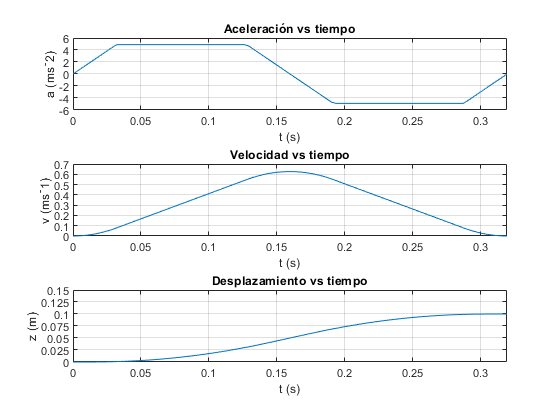

ts=linspace(0,tMax_a,100);

subplot(3,1,1)

plot(ts,a(ts))
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (ms^-2)')
ylim([-6 6])
xlim([0 double(tMax_a)])
yticks(-6:2:6)


subplot(3,1,2)

plot(ts,v(ts))
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (ms^-1)')
ylim([0 0.7])
xlim([0 double(tMax_a)])
yticks(0:0.1:0.7)

subplot(3,1,3)

plot(ts,Fz_arfada(ts))
title('Desplazamiento vs tiempo')
grid on
xlabel('t (s)')
ylabel('z (m)')
ylim([0 0.15])
xlim([0 double(tMax_a)])
yticks(0:0.025:0.15)



clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada ArfadaCaso1 ArfadaCaso2 ArfadaCaso3 CabeceoCaso1 CabeceoCaso2 CabeceoCaso3 BalanceoCaso1 BalanceoCaso2 BalanceoCaso3